# ばね-マス-ダンパ系 振動シミュレーション

運動方程式: $m\ddot{x} + c\dot{x} + kx = 0$

スライダーを動かすと、グラフが自動的に更新されます。

m    = 0.1;
k    = 50;
zeta = 0.21;

omega_n = sqrt(k / m);
c       = 2 * zeta * sqrt(m * k);

if zeta < 1,         state = '不足減衰（振動）';
elseif zeta <= 1.01, state = '臨界減衰';
else,                state = '過減衰'; end

fprintf('omega_n = %.3f rad/s  |  fn = %.3f Hz  |  %s\n', ...
    omega_n, omega_n/(2*pi), state);

omega_n = 22.361 rad/s  |  fn = 3.559 Hz  |  不足減衰（振動）


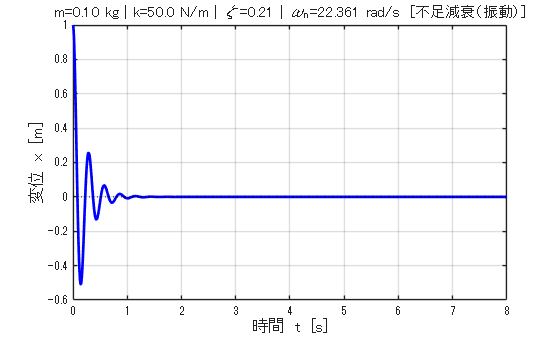


x0 = [1.0; 0.0];
tspan = [0, max(8, 5*2*pi/max(omega_n, 0.1))];
[t, y] = ode45(@(t,y) [y(2); -(c/m)*y(2)-(k/m)*y(1)], tspan, x0);

figure(1); clf;
plot(t, y(:,1), 'b-', 'LineWidth', 2);
yline(0, 'k:', 'LineWidth', 1);
xlabel('時間  t  [s]', 'FontSize', 12);
ylabel('変位  x  [m]', 'FontSize', 12);
title(sprintf('m=%.2f kg | k=%.1f N/m | \\zeta=%.2f | \\omega_n=%.3f rad/s  [%s]', ...
    m, k, zeta, omega_n, state), 'FontSize', 11);
grid on;

## 理論解説

**減衰比** $\zeta$ **による挙動の違い**

- $\zeta < 1$（不足減衰）：振動しながら減衰する

- $\zeta = 1$（臨界減衰）：振動せず最速で収束する

- $\zeta > 1$（過減衰）：振動せずゆっくり収束する

**固有角周波数と固有振動数**


$$\omega_n = \sqrt{\frac{k}{m}}, \qquad f_n = \frac{\omega_n}{2\pi}$$
